# Sessió 4 - Xavier Martin Ballesteros, Adrià Cabeza Sant'Anna

## Filtre laplacià

Filtrar la imatge amb el filtre laplacià ([0 1 0; 1 -4 1; 0 1 0]). Podeu usar 'imfilter'.

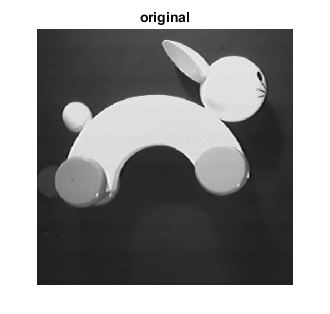

image = imread("rabbit.jpg");
image = double(image);
h = [0 1 0; 1 -4 1; 0 1 0];
image_filter = imfilter(image,h);
imshow(image,[]), title('original');
truesize([256 256])

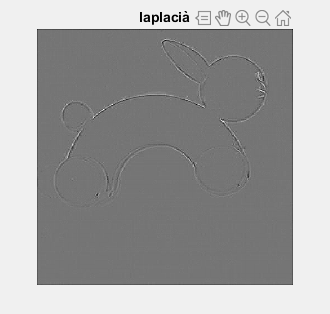

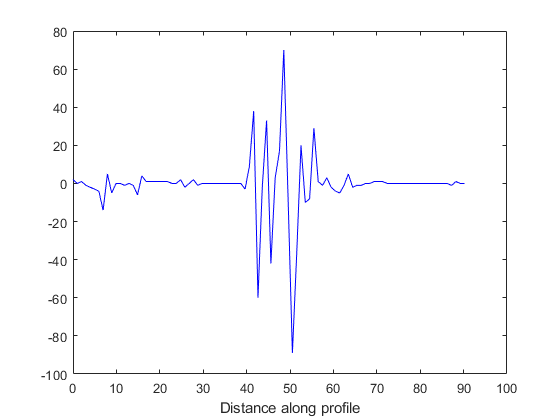

imshow(image_filter, []), title('laplacià');
truesize([256 256])
improfile

## Mòdul Gradient 

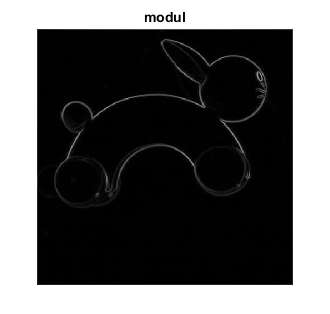

wx = [-1 0 1; -2 0 2; -1 0 1];
wx = wx/4;
Gx = imfilter(image, wx,'conv');
wy = wx';
Gy = imfilter(image, wy,'conv');
mod = sqrt(Gx.^2 + Gy.^2);
mod = uint8(mod);
figure, imshow(mod), title('modul')
truesize([256 256])

### Algorisme

Dissenyeu un algorisme PROPI per localitzar els pasos per zero del resultat del laplacià. 

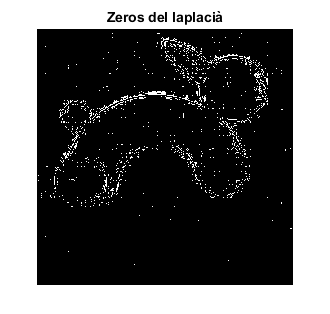

[rows,cols] = size(image_filter);
novaim = zeros(size(image_filter));
novaim2 = zeros(size(image_filter));
value = 3;
modul = 25;
for row = 2:(rows-1)
    for col = 2:(cols-1)
        if (( ((image_filter(row-1,col)< -value) & (image_filter(row,col) > value)) | ((image_filter(row,col-1)< -value) & (image_filter(row,col) > value)) | ((image_filter(row,col+1)< -value) & (image_filter(row,col) > value)) | ((image_filter(row+1,col)< -value) & (image_filter(row,col) > value))) & mod(row,col) > modul)
            novaim2(row,col) = 255;
        end
        if ( ((image_filter(row-1,col)< -value) & (image_filter(row,col) > value)) | ((image_filter(row,col-1)< -value) & (image_filter(row,col) > value)) | ((image_filter(row,col+1)< -value) & (image_filter(row,col) > value)) | ((image_filter(row+1,col)< -value) & (image_filter(row,col) > value)) )
           novaim(row,col) = 255;
        end
    end
end
imshow(novaim, []), title('Zeros del laplacià')
truesize([256 256])

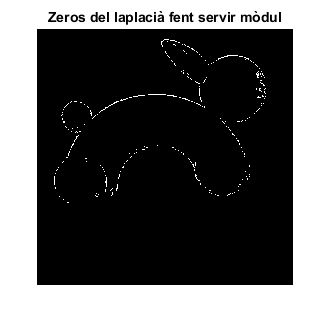

imshow(novaim2, []), title('Zeros del laplacià fent servir mòdul')
truesize([256 256])

## Algorisme de Canny

Apliqueu l'algorisme de Canny per a obtenir els contorns a partir de la imatge original. Useu la funció 'edge' i presenteu diferents resultats tunnejant els diferents paràmetres de la funció.

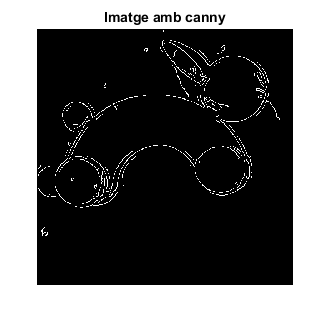

BW1 = edge(image, 'canny');
figure, imshow(BW1), title('Imatge amb canny');
truesize([256 256])

A continuació hem fet l'histograma de la imatge original per a veure en quin punt podríem posar el *threshold.*

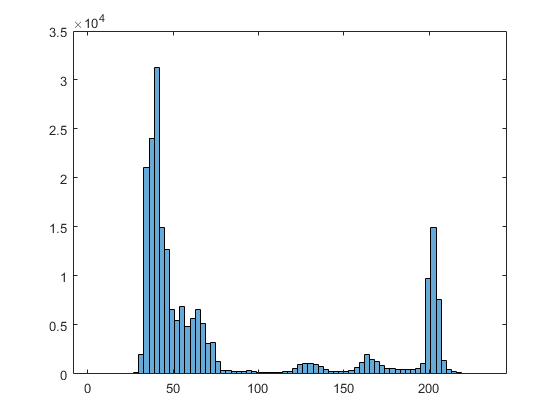

figure, histogram(image)

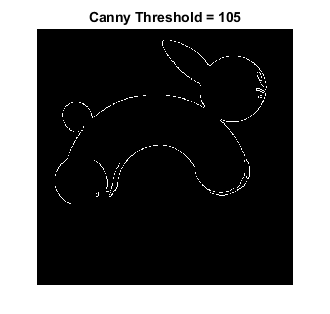

valor = 105/256;
BW2 = edge(image,'canny',valor);
figure, imshow(BW2), title('Canny Threshold = 105');
truesize([256 256])

Com podeu veure la silueta no està tancada del tot per la part inferior de l'esquerra, per això hem disminuit el *threshold.*

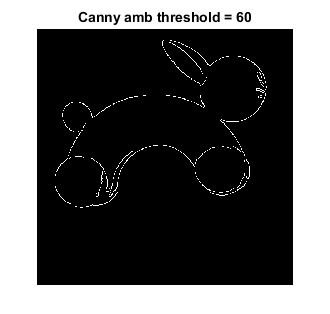

valor = 60/256;
BW3 = edge(image,'canny',valor);
figure, imshow(BW3), title('Canny amb threshold = 60');
truesize([256 256])

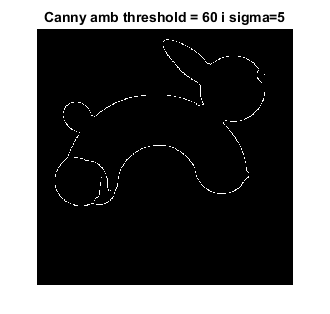


BW4 = edge(image, 'canny',valor,5);
figure, imshow(BW4), title('Canny amb threshold = 60 i sigma=5');
truesize([256 256])

Hem observat que quan més gran és el sigma més detall es perd.

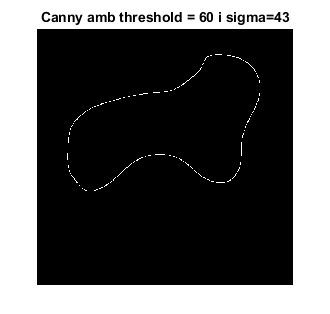

BW4 = edge(image, 'canny',valor,43);
figure, imshow(BW4), title('Canny amb threshold = 60 i sigma=43');
truesize([256 256])